# Workshop Weeks 8 & 9 - Spectral Analysis of EEG

In  the workshop in Weeks 8 & 9 you will implement methods to estimate the Power Spectral Denstiy of the LFP signal. The PSD of the LFP can be used to monitor the depth of anesthesia (DoA) experienced by a subject while the LFP is measured. The DoA is related to the delta ratio: the ratio of power in the delta band relative to the power in the theta-alpha-beta band. Generally a delta ratio above 0.1 indicates sufficient depth of anaesthesia. Monitoring DoA is an important practice during surgical operations such that the anesthesiologist is able to adjust the drug dose as necessary.

The estimates you will use to monitor DoA are the 

- Welch Estimate

- Bartlett Estimate

- Matlabs pwelch function.

## 1. Load Data

- Download and load the filtered LFP signal (lfp.mat) from the link [https://drive.google.com/drive/folders/1sxpn7NWBEYT7snqA_vXLRK-mqZqe2RCH?usp=sharing](https://drive.google.com/drive/folders/1sxpn7NWBEYT7snqA_vXLRK-mqZqe2RCH?usp=sharing)

- Extract values for the: length of the signal - $N$, lfp signal for channel 6 - $x$, time step between samples - $T = 1/f_s$.

load lfp.mat

N = length(t);
x = lfp(6,:);
T = 1/f_s;

## 2. Tutorial Exercise (not assessable)

Referring to ClassEx7_3b.m and corresponding lecture slides, implement the Bartlett Estimate of the PSD for the LFP signal $x$. Use a window length $M=20f_s+1$.

Figures:

- Figure 1a: Plot the final PSD estimate in [dB/Hz] on the domain (0 500) Hz

- Figure 1b: Plot the autocorrelation of the final PSD estimate.

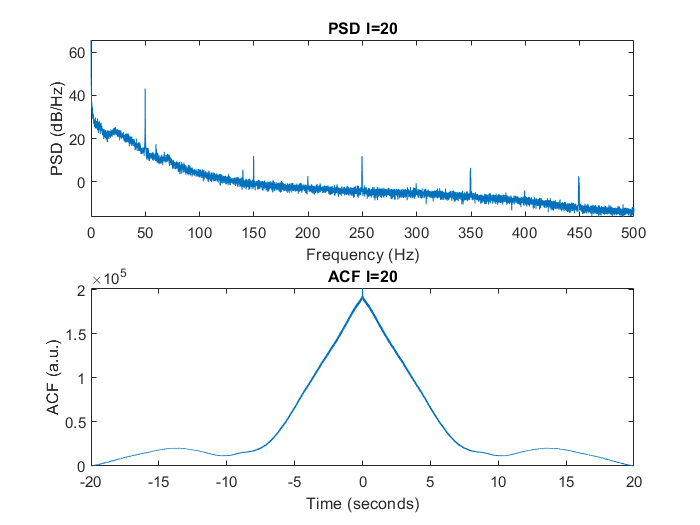

% window length 
M = 20*f_s + 1;

% window function
w = rectwin(M); 
w = w/norm(w); % normalised to unit energy

% number of segments
L = floor(N/M);

% signal re-shaping
X = reshape(x(1:L*M), M, L)'; % signal splitting
X = X.* repmat(w', L, 1);  % windowing

% initialisation
phi_sum = zeros(1,2*M-1); % ACF
S_sum =  zeros(1,M); % PSD

% corresponding positive frequency vector
f_Hz = (f_s/2)*(0:floor(M/2))/(M/2);

% estimate
for ll =1:L
    
    % ACF update
    phi_sum = phi_sum + xcorr(X(ll,:));
    
    % PSD update
    S_sum = S_sum + 2*T*abs((fft(X(ll,:)))).^2;
    
    % final PSD estimate plot
    figure(1);
    subplot(2,1,1);
    plot(f_Hz,10*log10(S_sum(1:floor(M/2)+1)/ll));
    xlabel('Frequency (Hz)');
    ylabel('PSD (dB/Hz)');
    title(['PSD l=' num2str(ll)]); 
    xlim([0 500]);
    
    % final ACF stimate plot
    figure(1);
    subplot(2,1,2);
    plot((-M+1:M-1)*T,phi_sum/ll);
    xlabel('Time (seconds)');
    ylabel('ACF (a.u.)');
    title(['ACF l=' num2str(ll)]); 
    %pause

end

## 3. Test independence of samples (1 mark)

- Calculate the autocorrelation of the signal $x$, and normalise this with respect to the peak. 

- On Figure 2 plot the normalised autocorrelation, $xx$, against a time lag vector $tt = ((-N+1):(N-1))*T$.

- Identify the lag time and therefore the window length in which the samples are relatively uncorrelated, i.e., $xcorr(x,x) < 0.2$ (Hint: look in the time lag interval (0 30)s). 

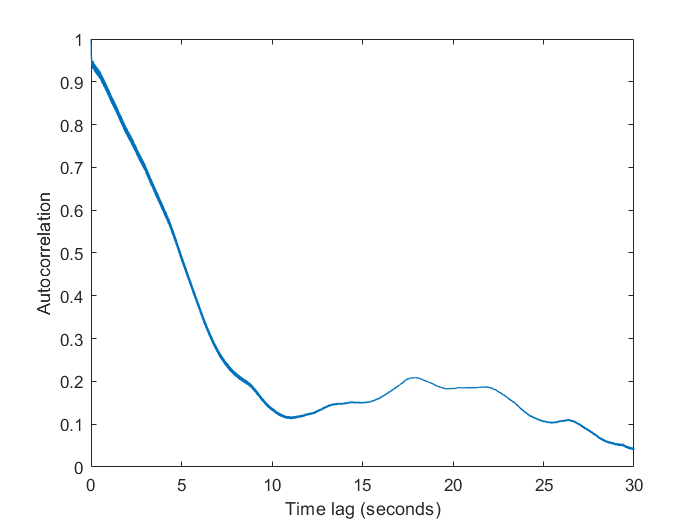

% signal ACF
x_corr = xcorr(x, 'biased');

% nomralise with respect to the peak
x_corr = x_corr/max(x_corr);

% time lag vector
tt = ((-N + 1):(N - 1))*T;

% normalised autocorrelation plot
figure(2);
plot(tt, x_corr);
xlim([0 30]);
xlabel('Time lag (seconds)');
ylabel('Autocorrelation');

From the Figure 2, the signal is relatively uncorrelated after 10 seconds

## 4. Welch Estimate (12 Marks)

During anesthesia, the DoA needs to be continuously monitored. Here we estimate DoA by implementing the Welch estimate of the PSD by using 100s sliding interval over the recording. Each time the interval is shifted the delta ratio will be updated. Use the following information:

- Using the autocorrelogram Figure  2, justify the choice of a peridogram length of 10s.

For the Welch estimate the signal should be relatively uncorrelated over the periodogram length. From Figure 2 the signal is correlated in the first 8 time lag seconds of the recoding. Thus, 10-second window allows to capture uncorrelated part of the signal

- Using the peridogram length of 10s, calculate the number of samples $M$ in this peridogram.

- Use a hann windowing function with length $M$ to compute the windowed function $w$. 

- The maximum number of peridograms in the signal is $Lmax = floor(N/M)$.

- The number of peridograms in 100s interval is $L2 = 10$.

- We want to calculate the Welch estimate using a 100s sliding interval over the peridograms. To do this, calculate the first PSD estimate on the peridograms 1 to 10, and the second estimate from 2 to 11, etc. 

Use this sliding interval PSD estimate, calculate the delta ratio over the recording. Use the following:

- Estimate the area under the PSD curves for the delta (0.5-4Hz) band, and the alpha/beta/theta (4-30Hz) band separately by using the inbuilt trapezoidal function trapz.

- The delta ratio is calculated as the ratio of the area under the PSD curve of the delta band to the area under the PSD curve of the alpha/beta/gamma band. (Hint: calculate the delta ratio of the sliding interval at the same time as you calculate the PSD for that 100s interval.)

% window length 
M = 10/T;

% window function
w_w = hann(M); % hann windowing
w_w = w_w/norm(w_w); % normalised to unit energy

% number of segments
Lmax_w = floor(N/M);

% numberof periodograms
L2 = 10;

% signal re-shaping
X_w = reshape(x(1:Lmax_w*M), M, Lmax_w)'; % signal splitting
X_w = X_w.* repmat(w_w', Lmax_w, 1);  % windowing

% corresponding positive frequency vector
f_Hz = (f_s/2)*(0:floor(M/2))/(M/2);

% initialisation
S_sum_w =  zeros(1,M);
S_w = zeros(1, M);
delta_ratio_w = zeros(1, Lmax_w - L2 + 1);

% periodograms
for ll =1:Lmax_w
    
    % PSD instantaneous
    S_sum_w(ll, :) = 2*T*abs((fft(X_w(ll,:)))).^2;

end

% corresponding freq indecies
delta_indecies = find(0.5 <= f_Hz & 4 >= f_Hz);
beta_indecies = find(4 <= f_Hz & 30 >= f_Hz);

% estimate
for kk = 1:(Lmax_w - L2 + 1)
    
    jj = kk:kk+L2-1;
    S_w(kk, :) = sum(S_sum_w(jj, :), 1)/L2;
    
    % instanteneous psd
    psd = sum(S_sum_w(jj, :), 1)/L2;
    psd = psd(1:floor(M/2)+1);
    
    % deta ratio calculations
    Adelta = trapz(f_Hz(delta_indecies), psd(delta_indecies));
    Aalpha = trapz(f_Hz(beta_indecies), psd(beta_indecies));
    delta_ratio_w(kk) = Adelta/Aalpha;
    
end

## 5. Bartlett Estimate (4 Marks)

Using the points above, implement  the Bartlett estimate in the same way to calculate the DoA over the course of the recording.

% window function
w_b = rectwin(M); % rect windowing
w_b = w_b/norm(w_b); % normalised to unit energy

% number of segments
Lmax_b = floor(N/M);

% signal re-shaping
X_b = reshape(x(1:Lmax_b*M), M, Lmax_b)'; % signal splitting
X_b = X_b.* repmat(w_b', Lmax_b, 1);  % windowing

% initialisation
S_sum_b =  zeros(1,M);
S_b = zeros(1, M);
delta_ratio_b = zeros(1, Lmax_b - L2 + 1);

% periodograms
for ll =1:Lmax_b
    
    % PSD instantaneous
    S_sum_b(ll, :) = 2*T*abs((fft(X_b(ll,:)))).^2;

end

% estimate
for kk = 1:(Lmax_w - L2 + 1)
    
    jj = kk:kk+L2-1;
    S_b(kk, :) = sum(S_sum_b(jj, :), 1)/L2;
    
    % instanteneous psd
    psd = sum(S_sum_b(jj, :), 1)/L2;
    psd = psd(1:floor(M/2)+1);
    
    % deta ratio calculations
    Adelta = trapz(f_Hz(delta_indecies), psd(delta_indecies));
    Aalpha = trapz(f_Hz(beta_indecies), psd(beta_indecies));
    delta_ratio_b(kk) = Adelta/Aalpha;
    
end

## 6. Visualise & Interpret (3 Marks)

Visualise and interpret the following graphs.

- Figure 3a: using the pwelch function: pwelch(x(1:M*L2),w,0,[],f_s,'onesided'), plot the PSD of the pwelch function, and your Welch estimate, on the domain (0 30) [Hz]. Ensure you have correct title, axis, and legend names. 

- Figure 3b: using the pwelch function: pwelch(x(1:M*L2),w_b,0,[],f_s,'onesided'), plot the PSD of the pwelch function with a Bartlett window (w_b), and your Bartlett estimate, on the domain (0 30) [Hz]. Ensure you have correct title, axis, and legend names. 

- Figure 4: visualise the delta ratio over the course of the recording. The x-axis should display time [s] with domain (55 355), and delta ratio is a unitless ratio. Ensure you have correct title, axis, and legend names. 

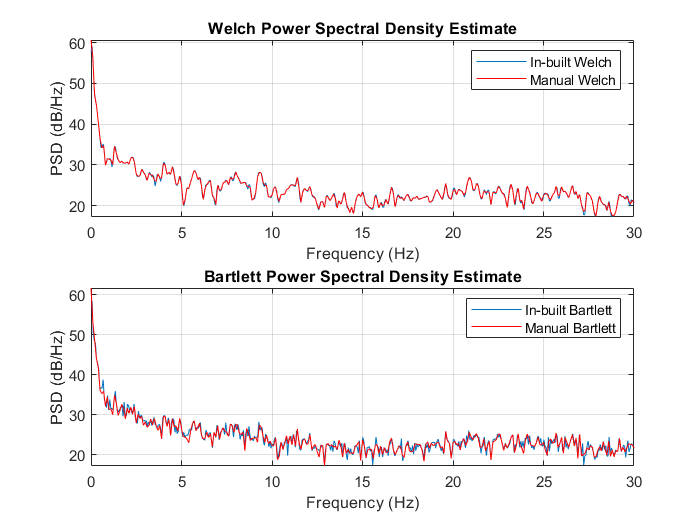

% figure 3
figure(3);

% Welch estimate
subplot(2, 1, 1);
pwelch(x(1:M*L2), w_w, 0, [], f_s, 'onesided');
hold on
plot(f_Hz, 10*log10(S_w(1, 1:floor(M/2)+1)), 'r');
xlim([0 30]);
xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
legend('In-built Welch', 'Manual Welch');

% Bartlett estimate
subplot(2, 1, 2);
pwelch(x(1:M*L2), w_b, 0, [], f_s, 'onesided');
hold on
plot(f_Hz, 10*log10(S_b(1, 1:floor(M/2)+1)), 'r');
xlim([0 30]);
xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
legend('In-built Bartlett', 'Manual Bartlett');
title('Bartlett Power Spectral Density Estimate')

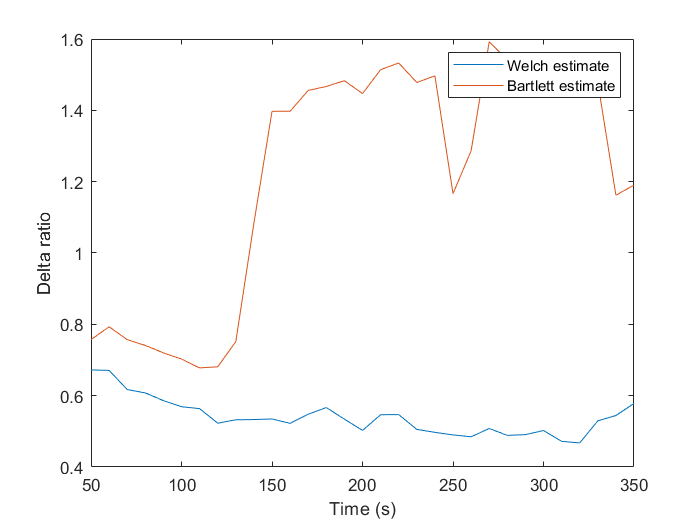


% figure 4
figure(4);
plot(50:10:350, delta_ratio_w);
hold on
plot(50:10:350, delta_ratio_b);
xlabel('Time (s)');
ylabel('Delta ratio');
legend('Welch estimate', 'Bartlett estimate');

- **Q: **How do the Welch and Bartlett estimates compare to each other? 

Manually calculated Welch and Bartlett estimates yielded rather similar results (in terms of general form of the PSDs). Due to its windowing, Welch estimate is much smoother than the Bartlett one. The major peaks are visible for both estimates, but Bartlett seems to depict them "smeared" and "squared off".

- **Q: **How does your Welch/Bartlett estimate compare to the matlab estimates? Are there any similarities or differences between these estimates? 

The manually calculated Welch estimate is almost identical to the matlab estimate with minor discrepincies from time to time. Bartlett estimates, however, while still similar share more differences than the Welch estimates. It almost seems like matlab estimate displays more peaks than the manually calculated one. Both manual and in-built estimates take an average of 10 periodograms and each segment is 10000 samples, so both estimates take the estimate over the first 100 seconds. That is however, only true for the first 10 periodograms plotted (i.e the first row of the manual estimate). The differences are larger when comparing the rest of the rows of the manual estimate. This is because, the manually calculated estimate takes an average over 10 periodograms per 100 seconds, while matlab version does not implement this sliding window.

- **Q: **Describe how the delta ratio varies over the signal recording? 

Delta ratio calculated using the two estimates yielded significantly different results. Delta ratio obtained from the Welch estimate gradually decreases over time, with noticeable two peaks at 180 and 220 seconds. At 350 seconds the ratio peaks again to 0.58. Bartlett estimate shows the opposite. At 150 seconds the delta ratio spikes to 1.4 and drop for a short period of time (20 seconds) to 1.7 and peaks again at 1.6. The estimates produced very different results not only in their behavioural pattern, but also in maximum values achieved. However, a clear pattern can still be established. Up to around 150 seconds alpha/beta/gamma band waves dominate, followed by an immediate increase in delta wave activity (subsequently decrease in alpha/beta/gamma). This means that the subject is under heavy anasthesia after 150 seconds.  

## 7. Time Domain Method (5 Marks)

The fft used in the calculation of the PSD involves significant computational time and could be an impediment to a real time implementation to estimate the delta ratio. Propose a method for calculating the delta ratio that can be *implemented* in the time domain (i.e. does not require use of the fft). Outline the steps required to implement your method in a few dot points. (You do not need to implement the method.)

**Answers:**

There is a clear relationship between total power and the power spectral density - power of a signal in a particular window, but former is in time domain, while the latter is in the frequency domain. Thus, delta ratio can be calculated in a similar way in the time domain space:

- Apply a Butterworth bandpass filter at 0.5-4Hz for delta wave and 4-30Hz for alpha/beat/gamma waves, separately

- Ideally a filtered signal would contain just the peaks associated with the freq ranges defined

- Identify the sample points (and subsequently time points) associated with the peaks for both freq ranges

- Divide the signal into 100-second windows for more accurate power estimates (maybe even partition the signal in the same way as done earlier, for better DoA accuracy)

- Take area under the curve to determine the power associated with the peaks  

- Calculate delta ratio

- Repeat the same thing for all time windows

## 8. Assignment Submission

BMEN90035WorkshopWeek8_9.m from canvas will serve as both your code and report file. Write your solutions in this file format and then publish this to a .pdf file. Please submit the following:

- The matlab code file ‘.m’ with file name ‘A5studentno.m’.

- The published matlab report with file name ‘A5studentno.pdf’. Use the inbuilt publish function in matlab to create a published version of the matlab code file. 

- A single file of any scanned mathematical derivations/solutions with file name ‘A5mstudentno.pdf’